# SNS Lab 11 

# (Part-1)

## Syed Muhammad Asad Ali

### sa09475

#### Task (1)

ftable = [1;2;3;4;5]*[80,110]

ftable =     80   110
   160   220
   240   330
   320   440
   400   550


fs = 8000; xx = [ ];
keys = rem(3:12,10) + 1;
for ii = 1:length(keys)
   kk = keys(ii);
   xx = [xx,zeros(1,400)];
   krow = ceil(kk/2);
   kcol = rem(kk-1,2) + 1;
   dur=0.15;
   t=0:1/fs:dur;
   xx = [xx, cos(2*pi*ftable(krow,kcol)*t)];
end
soundsc(xx,fs);

**1)** This program generates a long signal by concatenating cosine waves of specified frequencies from a frequency  table. It starts by defining ftable, which is a 5x2 matrix containing frequency pairs. It initializes an empty signal  vector xx and sets the sampling frequency fs to 8000 Hz. Then, it iterates through a sequence of keys (3 to  12 cyclically), calculates corresponding row and column indices (krow and kcol), defines the duration dur  of each cosine wave segment, and generates cosine waves using these parameters. These cosine waves are  concatenated to xx to form the final signal.

**2)** Five rows and two columns make up the 5x2 ftable matrix.  A pair of frequencies (in Hz) that correspond to the rows and columns of the DTMF keypad are represented by each entry in the ftable.  The keys vector determines the order in which the frequencies are played.  Using the ftable entries for each key, it generates cosine waves as it cycles through the integers 3 through 12 (modulo 10+1).

**3)**  Samples for each tone (0.15s duration):0.15×8000=1200 samples 

Silence samples per key press = 400 samples 

Total samples per key press = 1200+400=1600 

Since there are 10 key presses, the total number of samples in the signal is:10×1600=16000 samples

Total duration in seconds:160008000=2 seconds

#### Task 2

% test_dtmfdial.m
% Test case 1: Basic Test with a Single Key
keyNames = ['1'];
fs = 8000;
xx = dtmfdial(keyNames, fs);
disp('Test 1 (Single Key): Playing tone for key "1"');

Test 1 (Single Key): Playing tone for key "1"


soundsc(xx, fs); % Play the sound

pause(1); % Wait for the sound to finish

% Test case 2: Multiple Keys
keyNames = ['1', '3', '5'];
xx = dtmfdial(keyNames, fs);
disp('Test 2 (Multiple Keys): Playing tones for keys "1", "3", "5"');

Test 2 (Multiple Keys): Playing tones for keys "1", "3", "5"


soundsc(xx, fs);

pause(1);

% Test case 3: Larger Input
keyNames = ['1', '2', '3', '4', '5', '6', '7', '8', '9', '0'];
xx = dtmfdial(keyNames, fs);
disp('Test 3 (Larger Input): Playing tones for keys "1" to "0"');

Test 3 (Larger Input): Playing tones for keys "1" to "0"


soundsc(xx, fs);

In this code, we set the sampling frequency to 8000 Hz and create a DTMF signal for the characters mentioned above using the function dtmfdial we created. We then play the DTMF signal using the soundsc function, with the same sampling frequency.

#### Task 3

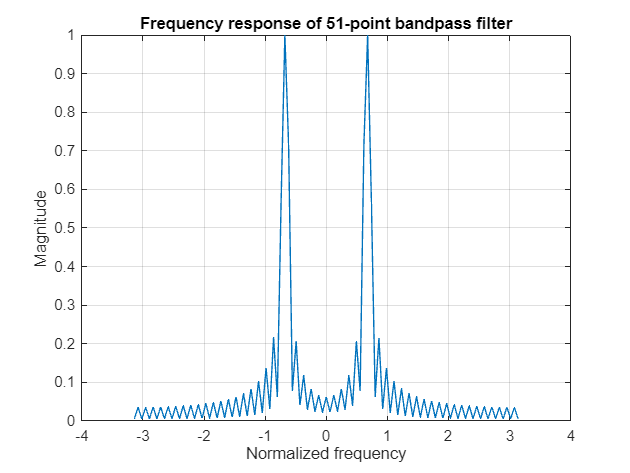

L= 51;
fb = 852;
fs = 8000;
B = maxbeta(L,fb,fs);

n=0:L-1;
hn = B.*cos(2.*pi*fb*n./fs);
ww = -pi:pi/L:pi;
H=abs(freqz(hn,1,ww));
plot(ww,H), 
grid on
title(['Frequency response of ', num2str(L), '-point bandpass filter']);
xlabel('Normalized frequency')
ylabel('Magnitude')

This code creates a Finite Impulse Response (FIR) filter with 51 samples and a cutoff frequency of 852 Hz.  First, we identify the proper scaling factor, B, using the maxbeta approach.  Next, we apply a cosine function with the desired cutoff frequency to create the impulse response of the filter.  After that, we normalize the impulse response by scaling it by multiplying it by beta.  The frequency response of the filter is then calculated using the freqz function and plotted against the normalized radian frequency axis.

#### Task 4

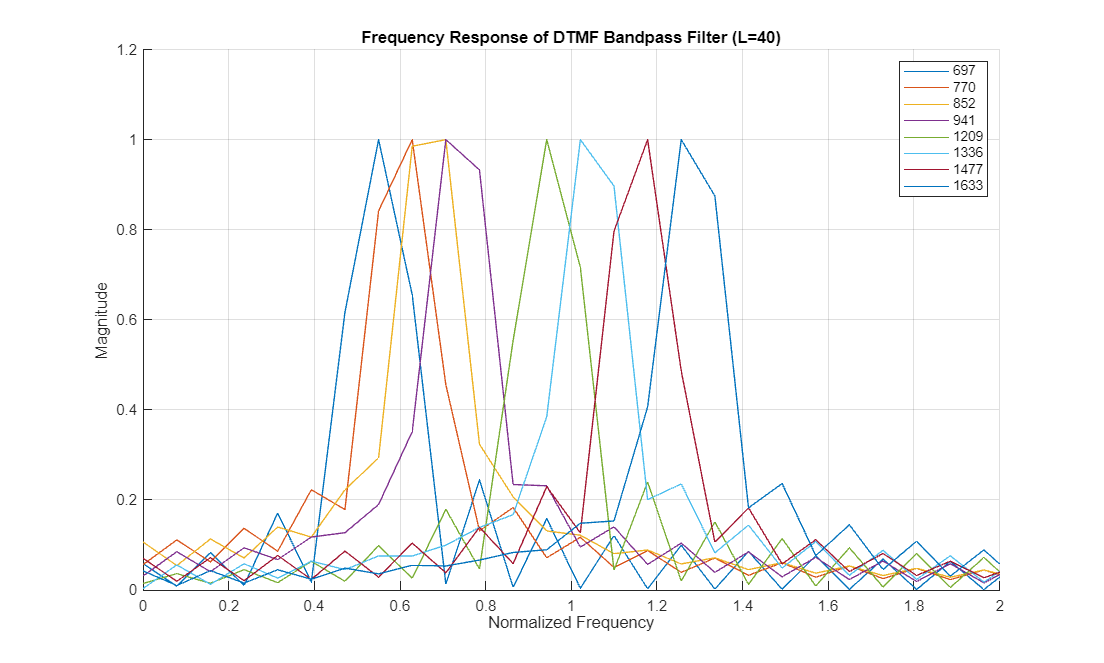

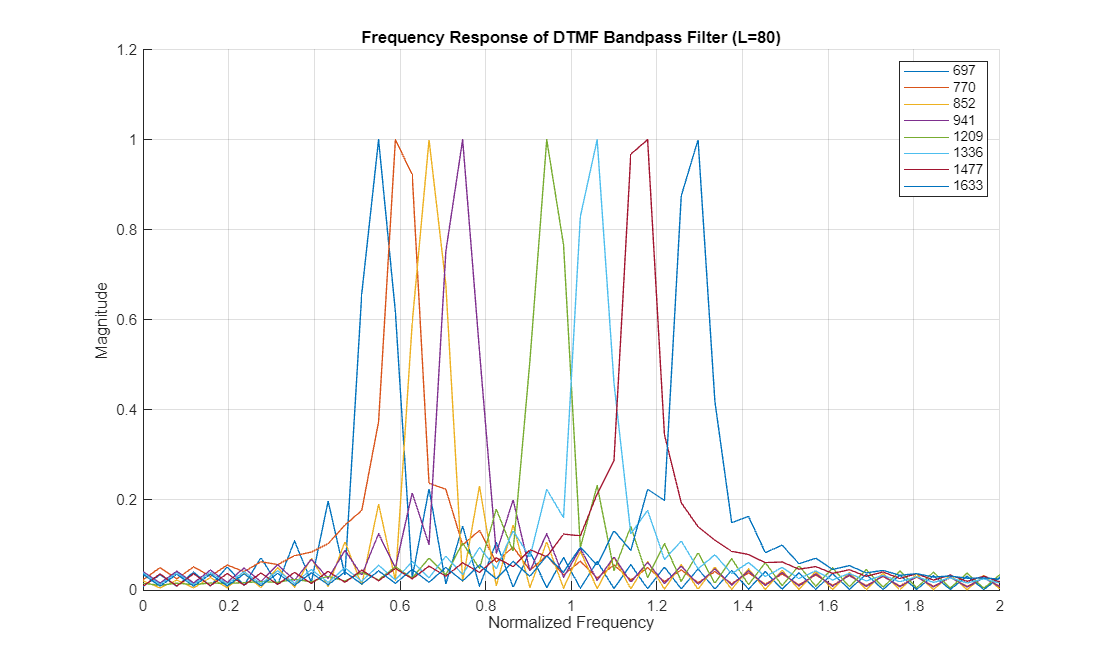

fs = 8000;
fb = [697, 770, 852, 941, 1209, 1336, 1477, 1633];  % DTMF frequencies
L_values = [40, 80];  % Different filter lengths
for L = L_values
   hh = dtmfdesign(fb, L, fs);
   figure('Position', [100, 100, 1000, 600]); 
   hold on;
   grid on;
   ww = 0:pi/L:pi;  % Normalized frequency range (0 to π)
    
   for k = 1 : length(fb)
       H = freqz(hh(:, k), 1, ww);  % Compute frequency response in normalized frequency
       plot(ww, abs(H));  % Plot magnitude against normalized frequency
   end
   hold off;
   title(['Frequency Response of DTMF Bandpass Filter (L=', num2str(L), ')']);
   xlabel('Normalized Frequency');
   xlim([0 2])
   ylabel('Magnitude');
   legend(arrayfun(@num2str, fb, 'UniformOutput', false));
end

This code examines the frequency response of Finite Impulse Response (FIR) filters designed for DTMF signals across various filter lengths (L). It illustrates how changes in filter length impact the attenuation and passband characteristics for different DTMF frequencies by plotting the response for each filter length individually. The results are then combined into a single plot for the final filter length. It is observed that as the filter length (L) increases, the passband width narrows and the peak becomes sharper. In the frequency response for different filter lengths, multiple frequencies appear in the passband, while other frequencies are attenuated, making it easy to identify which frequency passes through and which does not. For L = 40, the graphs show rounding at the top and significant overlap. At L = 80, the rounding is less pronounced and overlap is reduced, and at L = 150, there is no rounding and minimal overlap.

# (Part-2)

#### Task 5

Function made.

#### Task 6

Function made.

fs = 8000;
tk = ['A','B','C','D','*','#','0','1','2','3','4','5','6','7','8','9'];

Invalid use of operator.

Unrecognized function or variable 'A'.

xx1 = dtmfdial(tk, fs);
L= 200;
dtmfrun(xx1, L, fs)

#### Task 7

clc;
clear all;
close all;
phoneNum= ['4', '0', '7', '*', '8', '9', '1', '3', '2', 'B', 'A', 'D', 'C'];
% phoneNum= ['5']
fs=8000; %As this frequency has been used throughout the system
xx = dtmfdial(phoneNum, fs);

L = 200; 
Keys=dtmfrun(xx, L, fs)